Name: Saikrishna Saketh Y

Student Number: 723400

**A quick report**

- BER is observed to be 0 for 50% of the Simulation

- Selection Parameters of Fo, Fb, and Fs are chosen according to the underlying instructions, I chose Fo, which is strictly less than 15Khz

- Fb is chosen in such a manner that cycles/bit is an integer

- Roll off factor is Beta, which is chosen as 1, it provides most optimal bandwidth, 

- It observed at the end that of BER graph, last paet of the the BER approached very near to zero. Tx signal was at 89.5MHz, played by phone.

% Binary phase-shift keying + pulse shaping + FM transmitter
% and timing error detection and RTL-SDR 
%
% By R.W.

clear all, close all

% addpath ../funcs
% ==================================================================
%Script to set parameters
%rw_fmrx_init

% File to dump the output signal
fnam = 'bpsk_signal.wav';

% Parameters to choose:
%
Fs = 120e3;
Fo = 12e3;
Fb = 3e3;
KT = 0.1;
KP = 0.12;
KI = 0.12;
% Frequency of the information bits to send.
% Fo
% % Sampling rate of the FM modulator's input signal. 
% Note that the FM bandwidth is 15 KHz
% Fs
% Over-sampling factor in the audio file is therefore Fs/Fo
%
% Coefficients of the loop filter and the gain of the timing error
% detection
% KP, KI, KT
%
% Implement pulse shaping filter rw_pulse_shaping 
% Implement FM demodulator rw_fmrx
% Implement decimation to audio sampling rate rw_dec_audio
% Implement matched filter for the transmitted pulse rw_matched_pulse
% Implement derivative matched filter for the transmitted pulse rw_dmatched_pulse
% Implement timing error detection rw_inst_error
% Implement counter for the control loop rw_counter
% Implement matched filter for the preamble rw_matched_preamble
% 
% Except rw_fmrx, rw_lf_ted, and rw_counter these are on-line anonymous functions


% Preamble: Maximum length sequence
pnseq=comm.PNSequence('Polynomial',[5 2 0],'SamplesPerFrame',31,...
    'InitialConditions',[0 0 0 0 1]);
pn31 = sign(pnseq()' -0.5);
preamble = pn31;

% Typically the overhead from control signaling in wireless sytems is 10-20%
% Here preamble is the only control signal (no channel estimation, power
% control command, system information...) so the overhead can be smaller.
% It's arbitrary in this exercise anyway.
% #Information bits/message
Nbit = 300-length(preamble);
% Sets the seed for the random generator so that the message is always the
% same
rng(2308975234);
% Message consists of +- ones
msg = sign(randn(1,Nbit));

% A slot consists of the header and the payload
slot = [preamble,msg]; 
% A frame consists of Nslot slots
Nslot = 12;
frame = kron(ones(1,Nslot), slot);

% Make msg a column vector for the compatibility of dimensions
%msg = msg(:);

% front-end sampling rate, 
FESR = 240e3;
% #Slots to read over wireless, more than 1. This way there is at least one
% complete slot in one vector read by the dongle
Nradslot = 4;
Nsample = Nradslot*FESR/Fo*length(slot);
% #Output vectors to read from the dongle
Nloop = 100;

% ===========================================================================

## Part 1: Make the signal to transmit

Make a wav file that is then used as input to FM transmitter DBPSK odulation and shaping. Sine wave signals bit 1 Information signal for FM modulation at sampling frequency Fs

bpsk_signal = rw_pulse_shaping(frame,Fs/Fo);

% It's necessary to normalize the range [-1,1] for audiowrite
bpsk_signal = bpsk_signal/max(abs(bpsk_signal));

## Write the frame into audio file

This file is then transmitted with the FM transmitter Dongle has 8-bit analog-to-digital converter, so use the same number here

audiowrite(fnam,[bpsk_signal,bpsk_signal,bpsk_signal,bpsk_signal,bpsk_signal,bpsk_signal],Fs,'BitsPerSample',8,...
                'Title','BPSK signal','Artist','RW','Comment',date)
audioinfo(fnam)

ans = struct with fields:
             Filename: 'F:\Aalto\Course_Work_&_Modules\Period I-II 2018\Signal_Processing_for_Comm\Code\E5410-master\matlab\task9\bpsk_signal.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 120000
         TotalSamples: 216000
             Duration: 1.8000
                Title: 'BPSK signal'
              Comment: '16-Dec-2018'
               Artist: 'RW'
        BitsPerSample: 8



% The way to run audio in Ubuntu with Alsa 
%system('speaker-test -r sampling-rate -l 0 -t wav -W . -w fm_data.wav')
% 
% In /bin/bash
% while :; do afplay -r sampling-rate fm_data.wav; done
%
% Quicktime in Mac, Mediaplayer in Windows
% In Windows we play
%powershell -c (New-Object Media.SoundPlayer "c:\PathTo\YourSound.wav").PlaySync();
%
% Or upload to a phone and transmit
%
% Put your system to transmit until you move on to the receiver part


% ============================================================================

## Part 2: Receive

Radio parameters. Find an empty channel without any FM station

expFreq = 89.5e6;

hSDRrRx = comm.SDRRTLReceiver(...
    'RadioAddress', '0',...
    'CenterFrequency',     expFreq, ...
    'EnableTunerAGC',      true, ...
    'SampleRate',          FESR, ...
    'SamplesPerFrame',     Nsample, ...
    'FrequencyCorrection', 70, ...
    'OutputDataType',      'double');

hSpectrumAnalyzer = dsp.SpectrumAnalyzer(...
    'Name',             'Actual Frequency Offset',...
    'Title',            'Actual Frequency Offset', ...
    'SpectrumType',     'Power density',...
    'FrequencySpan',    'Full', ...
    'SampleRate',       FESR, ...
    'YLimits',          [-60,10],...
    'SpectralAverages', 10, ...
    'FrequencySpan',    'Start and stop frequencies', ...
    'StartFrequency',   -50e3, ...
    'StopFrequency',    50e3,...
    'Position',         figposition([50 30 30 40]));

## Rx loop

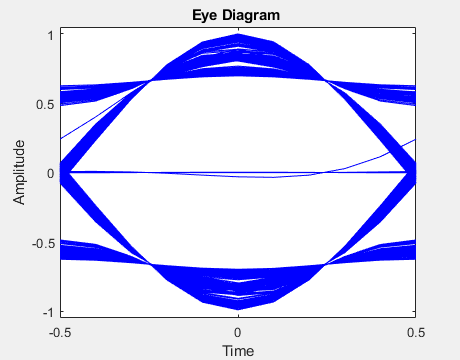

if isempty(sdrinfo(hSDRrRx.RadioAddress))
    warning(message('SDR:sysobjdemos:MainLoop'))
    return
end

% Allocate memory for signal storage
%rxSigStore = zeros(1,Nsample*Nloop);
ber_vec = ones(1,Nloop);
% Matched filter output after synchronization
ymf = zeros(1,Nsample*Fo/FESR);
fa = figure('Name','timing accumulator'); 
fb = figure('Name', 'BER');
hb = animatedline('Marker','o');
axis([0 Nloop 0 1]);
% Handle for the eye diagram
L=Fs/Fo;
heye = eyediagram(bpsk_signal,L);    

idx_over=0; idx_under=0;

% Time elapsed
fprintf('Loop time: %f s\n',Nsample*Nloop/FESR)

Loop time: 10.000000 s


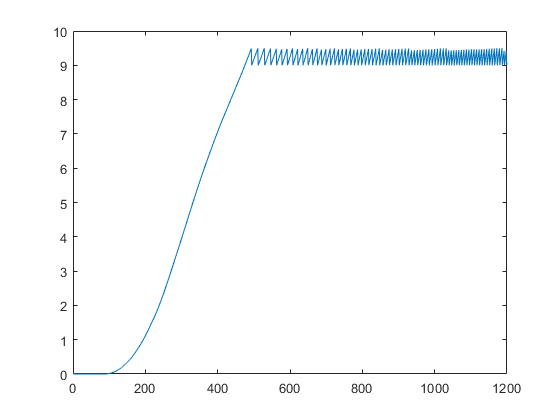

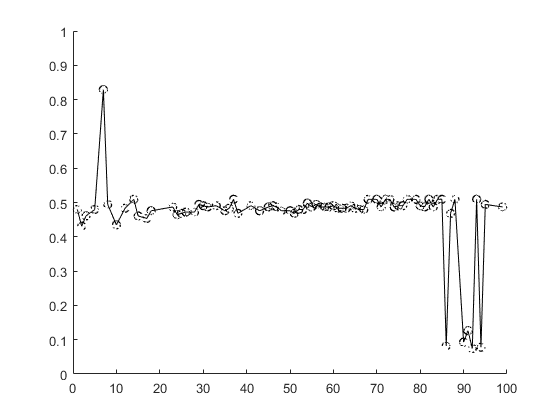

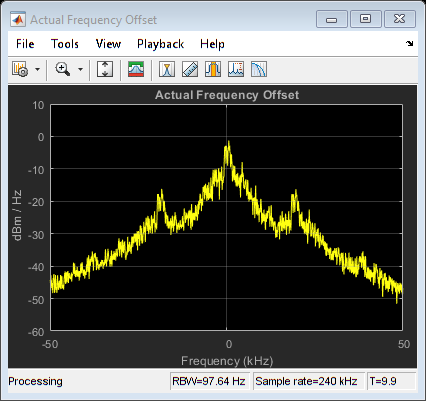

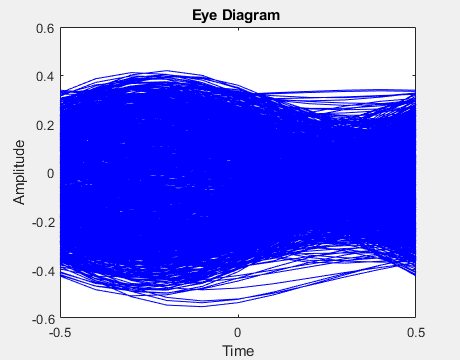

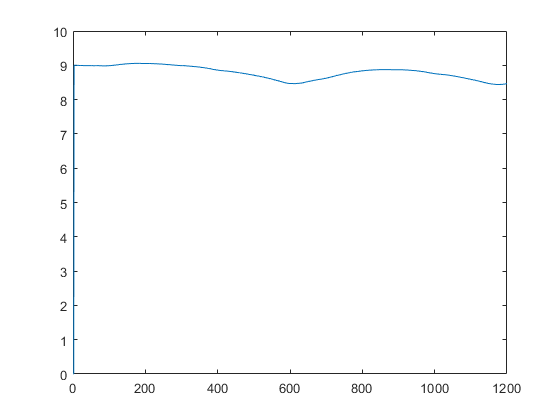

tstart = tic;
for ii = 1:Nloop
    [rxSig, ~] = step(hSDRrRx);
    rxSig = rxSig - mean(rxSig);  % Remove DC component
        
    % Display received frequency spectrum
    hSpectrumAnalyzer(rxSig);
    
    %rxSigStore((iFrame-1)*SPF+[1:SPF]) = rxSig;
    % FM demodulator using discriminator
    rd = rw_fmrx(rxSig,FESR);
    % Decimate to audio sampling rate first
    rd_audio = rw_dec_audio(rd,FESR/Fs);
    % Matched filtering and derivative MF of the pulse shaping filter
    after_mf = rw_matched_pulse(rd_audio,Fs/Fo); 
    after_dmf = rw_dmatched_pulse(rd_audio,Fs/Fo);
    
    % Option to vheck that the Tx-Rx chain works without over-the air transmission
    % Note that the length is not the same as length(rd_audio)
    % Comment out when it works
    %after_mf = rw_matched_pulse(bpsk_signal(:));
    %after_dmf = rw_dmatched_pulse(bpsk_signal(:));
    % Plot to the same eye diagram using figure handle heye
    eyediagram(after_mf,L,1,0,'b-',heye);
    
    % Search for the timing
                ptr = 0; accu=0;  lstate=0;
                % Symbol clock, L times slower than the audio sampling rate
                kk = 0;
                for jj = 1:L:length(after_mf)
  
                               kk = kk+1;
                               % Matched filter output at the estimated time instant
                               ymf(kk) = after_mf(jj+ptr);
                               % Instantaneous timing error
                               err = KT*rw_inst_error(ymf(kk),after_dmf(jj+ptr));
               
        % 1st order loop filter function
        % Input: loop filter coefficients, instantaneous error, internal
        % state
                               [t_err, lstate] = rw_lf_ted(KP,KI,err,lstate);

        % Counter to control the sampling.
                               % Update accumulator with the filtered timing error such 
        % that it stays in the range [0,L-1]
        accu = rw_counter(t_err, accu, L);

        % Indices must be integers
                               ptr = round(accu);
                               v_accu(kk) = accu;
                end  % Timing loop
    % Check the performance of the timing loop
    % Comment out if the loop slows down
                figure(fa), plot(v_accu), drawnow limitrate
    
    % Find the preamble using the  preamble sequence
    % Phase can be flipped so use abs()
    after_premf = rw_matched_preamble(ymf,preamble);
    [~, idx] = max(abs(after_premf));
    
    % Channel phase estimation
    if after_premf(idx)<0, ymf = -ymf; end
    
    % If the index is too large so that the slot cannot start here,
    % don't attempt to decode and go read a new sample vector
    if idx+Nbit > Nradslot*Nbit, continue,  end

    % Index OK, decode
    msgd = sign(ymf(idx+[1:Nbit]));  

    % Bit-error rate
    ber_vec(ii) = sum(msg~=msgd)/Nbit;
    %fprintf('Bit error rate %f at round %d\n', ber_vec(ii), ii)
    % Plot BER point by point. Comment out if too slow
    addpoints(hb, ii, ber_vec(ii)), drawnow limitrate
end

fprintf('Elapsed time %f s\n', toc(tstart))

Elapsed time 107.092668 s


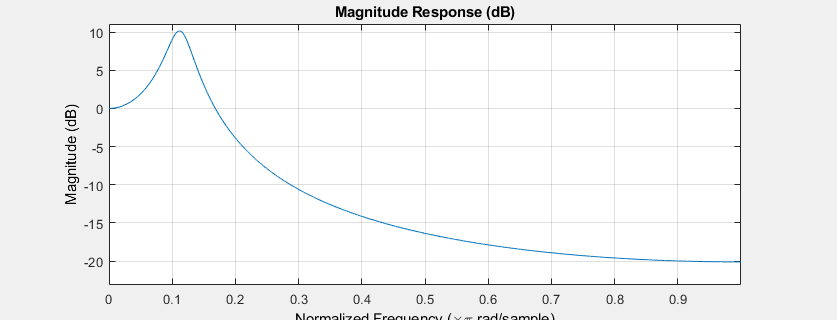

 
fvtool([0 KP+KI -KP],[1 -2*(1-0.5*(KP+KI)) 1-KP])

% Check the bit-error rates
%stem(ber_vec)

## Release all System objects

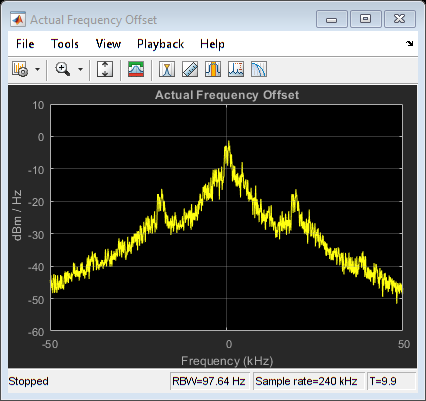

release(hSDRrRx); 
release(hSpectrumAnalyzer)

clear hSDRrRx


function dbpsk_signal = rw_pulse_shaping(frame,upsampling)
   raised_cosine = rcosdesign(1,16,upsampling);
   dbpsk_signal = filter(raised_cosine, 1, upsample(frame,upsampling));
end

function rd = rw_fmrx(rxSig,FESR)
    filterdelay = filter([0 1],1,rxSig);
    rd = angle(filterdelay .* conj(rxSig));
    FLOW = fir1(50,15e3/(FESR/2));
    memo = zeros(1, length(FLOW)-1);
    [rd,~]=filter(FLOW,1,rd,memo);
end

function rd_audio = rw_dec_audio(rd,factor)
    rd_audio = rd(1:factor:end);
end

function after_mf = rw_matched_pulse(rd_audio,upsampling)
     raised_cosine = rcosdesign(1,16,upsampling);
     after_mf = filter(raised_cosine,1,rd_audio);
end

function after_premf = rw_matched_preamble(after_mf,preamble)
    after_premf = filter(fliplr(preamble),1,after_mf);
end

function after_dmf = rw_dmatched_pulse(rd_audio,upsampling)
    raised_cosine = rcosdesign(1,16,upsampling);
    diff = [1 0 -1];
    dmf = filter(diff,1,raised_cosine);
    after_dmf = filter(dmf,1,rd_audio);
    
end

function [t_err, lstate] = rw_lf_ted(KP,KI,err,lstate)
    t_err = KP*err + KI*err + lstate;
    lstate = KI*err+lstate;
end

function err = rw_inst_error(ymf,after_dmf)
    err = ymf.*after_dmf;
end

function accu = rw_counter(t_err, accu, L)
    accu = mod(t_err+accu,L);
    if(accu > 9.5)
        
        accu = 9;
    end
end